# **Matlab案例代码解析**

## 2. 典型绘图案例

### 2.6 特殊绘图

#### 2.6.6 梯度下降法的下降方向

颜值即正义；

**颜色模板参考：**[**60套优雅的颜色模板**](https://zhuanlan.zhihu.com/p/444970597)

clear;clc;close all;
% 获取到颜色
[all_themes, all_colors] = GetColors(); 
% 创建一个 colormap
map = GenColormap(all_themes{1});
%% 一元函数梯度下降法
% 示例：f(x) = min{(x - 1)^2}
% 梯度：g(x) =  2 * (x - 1)
% 学习率，一般设置小一点，否则容易在最小值附近震荡或者不收敛
yita = 0.25;   
x1 = -5 : 0.1 : 5;
y1 = (x1 - 1).^2;
iteMax = 1000;
xInit = 4;
yInit = (xInit - 1)^2;
err = 1e-6;
figure('Position', [50, 50, 900, 400]);
tiledlayout(1, 2, 'TileSpacing', 'compact');
nexttile
plot(x1, y1, 'b', 'LineWidth', 2)
xlim([-5, 5])
ylim([-1, 25])
hold on
plot(xInit, yInit, 'ok', 'MarkerFaceColor', 'k')
for i = 1 : iteMax
    % x = x + yita * grad;
    xNew = xInit - yita * 2 * (xInit - 1);
    yNew = (xNew - 1)^2;
    % 退出条件
    if abs(xNew - xInit) < err
        break;
    else
        PlotLineArrow(gca, [xInit, xNew], [yInit, yNew], 'k', 'k', 2)
        xInit = xNew;
        yInit = yNew;
        disp(['第', num2str(i), '次迭代结果：', num2str(xInit)]);
        plot(xNew, yNew, 'ok', 'MarkerFaceColor', 'k')        
    end
end

第1次迭代结果：2.5


第2次迭代结果：1.75


第3次迭代结果：1.375


第4次迭代结果：1.1875


第5次迭代结果：1.0938


第6次迭代结果：1.0469


第7次迭代结果：1.0234


第8次迭代结果：1.0117


第9次迭代结果：1.0059


第10次迭代结果：1.0029


第11次迭代结果：1.0015


第12次迭代结果：1.0007


第13次迭代结果：1.0004


第14次迭代结果：1.0002


第15次迭代结果：1.0001


第16次迭代结果：1


第17次迭代结果：1


第18次迭代结果：1


第19次迭代结果：1


第20次迭代结果：1


第21次迭代结果：1


hold off
title('梯度下降');

%% 多元函数梯度下降法
% 示例：f(x) = min{x1^2 + x2^2}
% 梯度：g(x) = [2 * x1; 2 * x2]
[x, y] = meshgrid(-5:0.5:5, -5:0.5:5);
z = x.^2 + y.^2;
initX = 4;
initY = 3;
initZ = initX^2 + initY^2;
initValue = [initX; initY];
nexttile
contourf(x, y, z, 20);
colormap(map);
shading interp
hold on
grad = zeros(1, 2);
e = 0.1;
yita = 5;   % Adagrad 更快收敛
for i = 1 : iteMax
    % 标准的梯度法  x = x + yita * grad;
%     newValue = initValue - yita * [2 * initX; 2 * initY];
    % Adagrad 法    x = x + yita * inv(G) * grad;
    grad = grad + [(2 * initX)^2, (2 * initY)^2];
    newValue = initValue - yita * diag(1 ./ sqrt(grad + e)) * [2 * initX; 2 * initY];
    % 退出条件
    if norm(newValue - initValue) < err
        break;
    else
        newX = newValue(1);
        newY = newValue(2);
        newZ = newX^2 + newY^2;
%         plot([initX, newX], [initY, newY], '-ok', 'MarkerFaceColor', 'r')
        PlotLineArrow(gca, [initX, newX], [initY, newY], 'k', 'k', 2)
        initValue = newValue;
        initX = newX;
        initY = newY;
        initZ = newZ;
        disp(['第', num2str(i), '次迭代结果：', num2str(newValue')]);    
    end
end

第1次迭代结果：-0.9961     -1.9931


第2次迭代结果：0.21124      0.7711


第3次迭代结果：-0.044461    -0.27468


第4次迭代结果：0.009355    0.096817


第5次迭代结果：-0.0019683    -0.03408


第6次迭代结果：0.00041415    0.011994


第7次迭代结果：-8.7139e-05  -0.0042213


第8次迭代结果：1.8335e-05   0.0014857


第9次迭代结果：-3.8577e-06 -0.00052286


第10次迭代结果：8.1168e-07  0.00018402


第11次迭代结果：-1.7078e-07 -6.4762e-05


第12次迭代结果：3.5933e-08  2.2793e-05


第13次迭代结果：-7.5606e-09 -8.0216e-06


第14次迭代结果：1.5908e-09  2.8231e-06


第15次迭代结果：-3.3471e-10 -9.9357e-07


第16次迭代结果：7.0425e-11  3.4968e-07


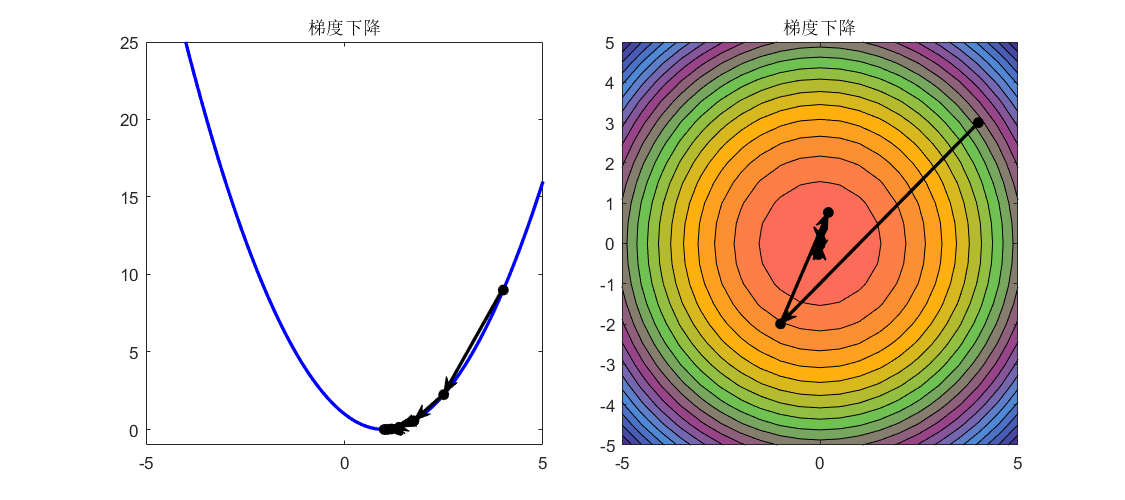

hold off
title('梯度下降');